# Optimal Detection for the Vector AWGN Channel (minimum-distance detector)

This function estimates noisy complex symbol values using the minimum Euclidean distance as an estimator with respect to some QAM constellations.

**Inputs:**

- *symb_RX*: noisy RX symbol vector of size *nb_symb x 1 *where *nb_symb = nb_bit / nb_bit_per_symb*

- *nb_bit_per_symb*: number of bits per symbol

- *nb_symb*: number of symbols in the  symbol stream (= length of *symb_RX*)

**Ouputs:**

- *symb_RX_estimated*: estimated complex symbol stream vector of size *nb_symb x 1* where *nb_symb = nb_bit / nb_bit_per_symb*

function symb_RX_estimated = symbol_estimation_QAM( symb_RX , nb_bit_per_symb , nb_symb )

## Minimum-distance detector: theory

This function implements an optimal detection in the case of a transmission over an additive white Gaussian noise (AWGN) channel whose vector representation can be written as:

$\mathbf{r}=\mathbf{s_m}+\mathbf{n}$,          $1\leq m \leq M$

where $\mathbf{r}$ is the received symbol, $\mathbf{s_m}$ is the transmitted symbol among $M$possible symbols within a given constellation, and $\mathbf{n}$ is a white Gaussiance noise (i.e., its real and imaginary components are i.i.d. zero-mean Gaussian random variables with variance $\frac{N_0}{2}$). The vectors considered here are 2-dimensional vectors from a 2D orthonormal plane, and can therefore be conveniently represented in a complex plane (i.e., 2D symbol space <=>  IQ plane: $\mathbf{s_m}=\{ I_m, Q_m \}$).

The role of the estimator at the receiver is to decide which symbol has been sent based on the observation of $\mathbf{r}$, so the optimal decision rule can be written as:

$\hat m = \arg\max_{1\leq m \leq M} P_mp (\mathbf{r} \mid\mathbf{s_m})$, where $P_m$ is the *a priori* probability of a given symbol $\mathbf{s_m}$ being transmitted and $p (\mathbf{r} \mid\mathbf{s_m})$ is the conditional probability density function of the received symbol $\mathbf{r}$ knowing $\mathbf{s_m}$ has been transmitted. This is known as the **maximum a posteriori probability (MAP)** rule. It consists in selecting the symbol index $m$ within a *M*-size that by maximizes the probability $P_mp (\mathbf{r} \mid\mathbf{s_m})$.

In the case of equiprobable symbols (i.e., there is the same probability for all symbols within a constellation to be transmitted), $P_m = \frac{1}{M}$ for all  $1\leq m \leq M$. The optimal detection rule reduces then to: $\hat m = \arg\max_{1\leq m \leq M} p (\mathbf{r} \mid\mathbf{s_m})$. This is known as the **maximum likelihood estimator (MLE)** *(the MLE is not optimal unless symbols are equiprobable in their occurence).*

In the scenario of a vector AWGN channel and assuming equiprobability between symbols, both MAP and MLE can be implemented by a **minimum-distance (or nearest-neighbor) detector**:

$\hat m = \arg\min_{1\leq m \leq M} \mid\mid \mathbf{r} - \mathbf{s_m} \mid\mid $.

For more details regarding optimal receiver, see chapter 4 from *"Digital Communications", 5th Edition, J.G Proakis and M. Salehi, McGraw Hill*

## Guidelines: what to do?

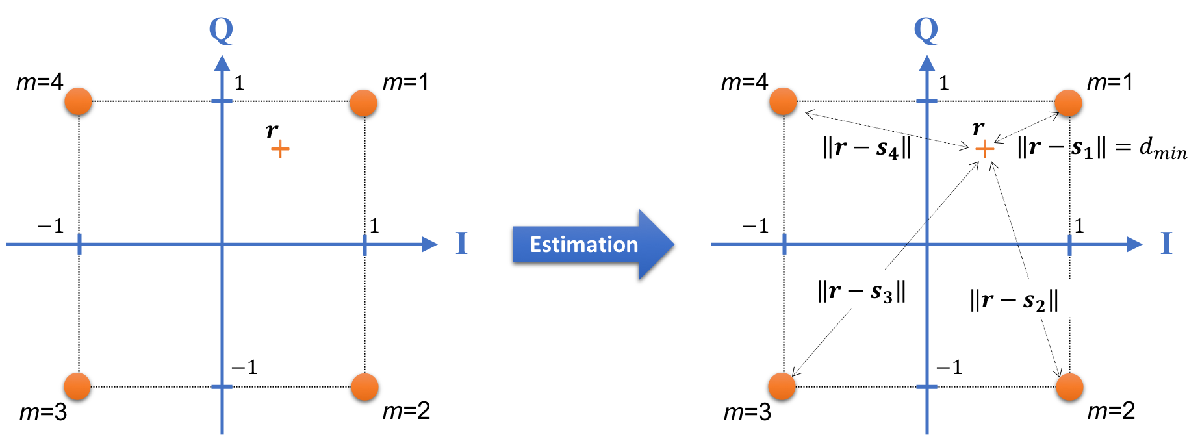

The receiver receives $\mathbf{r}$ and looks among all $\mathbf{s_m}$ to find the one that is closest to $\mathbf{r}$ using standard Euclidean distance. This needs to be done for QPSK and 16QAM mapping.

In the above example, if the input symbol is *symb_RX *= **r**, the ouput should then be *symb_RX_estimated* = 1 + 1i, since the m=1 symbol is the one that minimizes the Euclidean distance between the received symbol and the symbols from the original constellation.

## 4QAM constellation (<=> QPSK)

The QPSK constellation is as shown below:

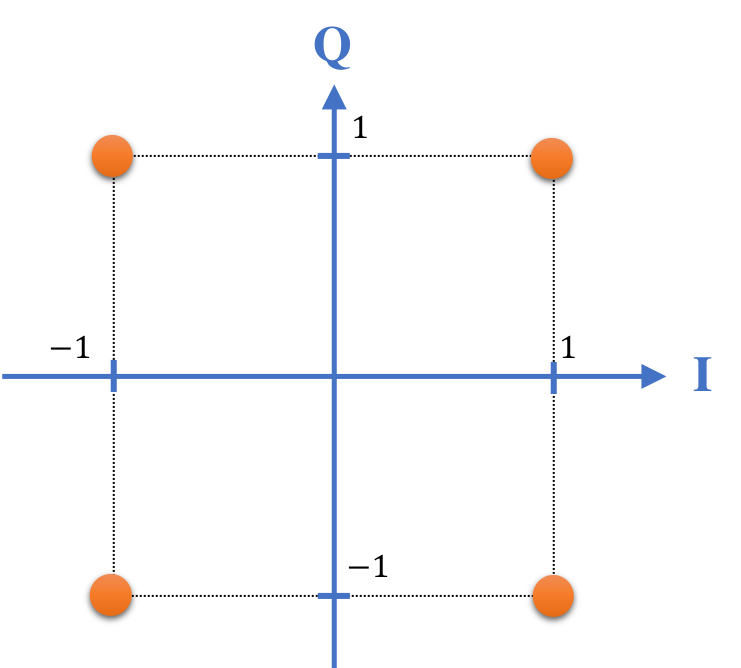

if nb_bit_per_symb == 2
    QAM_4 = [-1-1i, -1+1i, 1+1i, 1-1i];
    % Code here the symbol estimation function for QPSK constellation (output: symb_RX_estimated)
    for i = 1:nb_symb
        % Calculate Euclidean distance from symb_RX(k) to all 4QAM constellation points
        d1 = abs(symb_RX(i) - QAM_4(1));
        d2 = abs(symb_RX(i) - QAM_4(2));
        d3 = abs(symb_RX(i) - QAM_4(3));
        d4 = abs(symb_RX(i) - QAM_4(4));
        z = min(min(d1,d2),min(d3,d4));
        if z == d1 
            idx = 1;
        elseif z == d2 
            idx = 2;
        elseif z == d3 
            idx = 3;   
        elseif z == d4 
            idx = 4;  
        end
        % Assign the closest constellation point to symb_RX_estimated
        symb_RX_estimated(i,1) = QAM_4(idx);
    end
end
 


## 16QAM constellation

The 16QAM constellation is as shown below:

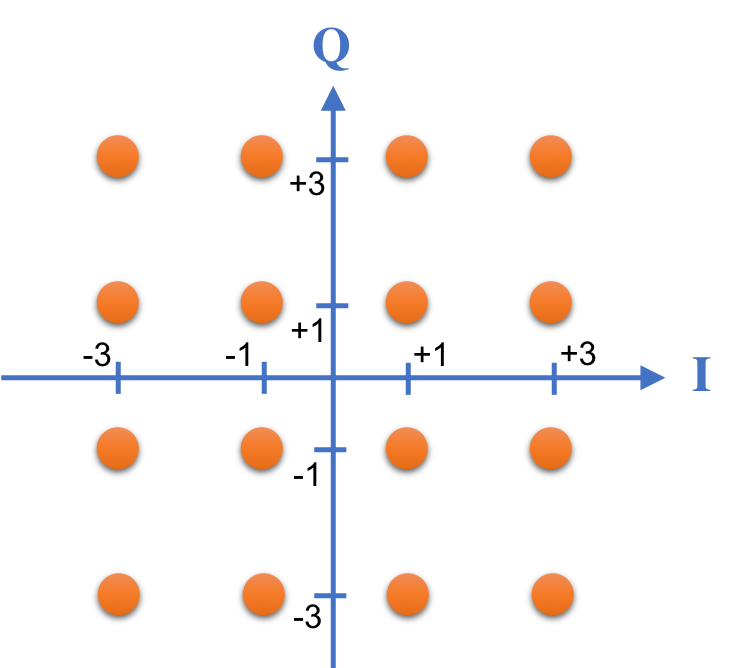

if nb_bit_per_symb == 4
    
    %Qam_16 =   0000 ,  0001 ,  0010 ,  0011 ,  0100 ,  0101 ,  0110 ,  0111 , 1000 , 1001 , 1010 , 1011 , 1100 , 1101 , 1110 , 1111  
    QAM_16 = [ -3+3i , -3+1i , -3-3i , -3-1i , -1+3i , -1+1i , -1-3i , -1-1i , 3+3i , 3+1i , 3-3i , 3-1i , 1+3i , 1+1i , 1-3i , 1-1i ];

    symb_RX_estimated = zeros(nb_symb, 1);
    
    for i = 1:nb_symb
        
        distances = abs(symb_RX(i) - QAM_16);
        
        
        [~, idx] = min(distances);
        
        
        symb_RX_estimated(i) = QAM_16(idx);
    end

end